# showing basic results     

## Recollect all data

load results_BrainBonus2_Laplace.mat
recollect_data

## display subplots of time trials

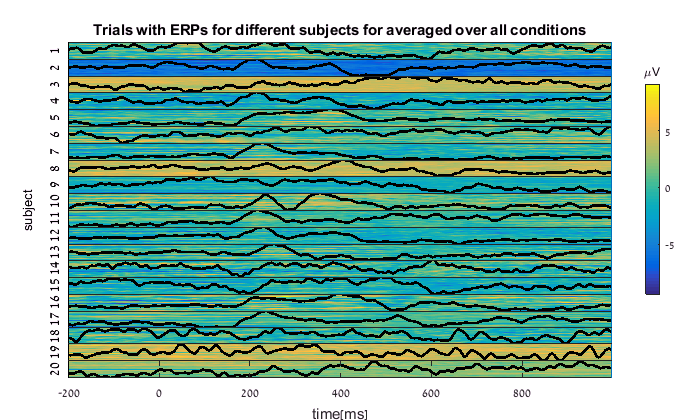

figure;
mtrials = [0,inf];
ha = tight_subplot(length(results),1,0,0.1,[0.1, 0.1]);
for ii = 1:length(results)

    %     subplot(length(results),1,ii)
    axes(ha(ii));
    
    trials = squeeze(results{ii}.trials(u,1,:));
    trials = bsxfun(@minus, trials, mean(trials(bl_range,:),1))';
    erps = mean(results{ii}.erps,2);

    imagesc(t,1:size(trials,2),trials)%,'edgecolor','none');
    caxis([min(trials(:)) max(trials(:))]);
    
    view(0,90);
    axis tight;
    shading interp; %colormap(parula(128));
    set(gca,'YTick',[]);
    ylabel(ii)
    
    hold on
    yyaxis right
    mx = max(erps(u));
    mn = min(erps(u));
    erp = ((erps(u) - mn)/(mx-mn))*(size(trials,2)-1) + 1;
    plot(t, erp, 'linewidth',2,'color','k');

    set(gca,'XTick',[]);
    set(gca,'YTick',[]);
%     caxis([min(trials(:)), max(trials(:))])
end

% axes(ha(floor(length(results)/2)))
hy = axes('Position',[0 0 1 1],'Xlim',[0 1],'Ylim',[0 1],'Box','off','Visible','off','Units','normalized', 'clipping' , 'off');
text(0.04, 0.5,'subject','VerticalAlignment' ,'middle','HorizontalAlignment', 'center', 'Rotation', 90);

axes(ha(end))
xlabel time[ms]
set(gca,'XTickMode', 'auto')

axes(ha(1))
title('Trials with ERPs for different subjects for averaged over all conditions')

h = colorbar;
title(h,'\muV');
set(h, 'Position', [.95 0.3 0.02 0.5])

## display subplots of power

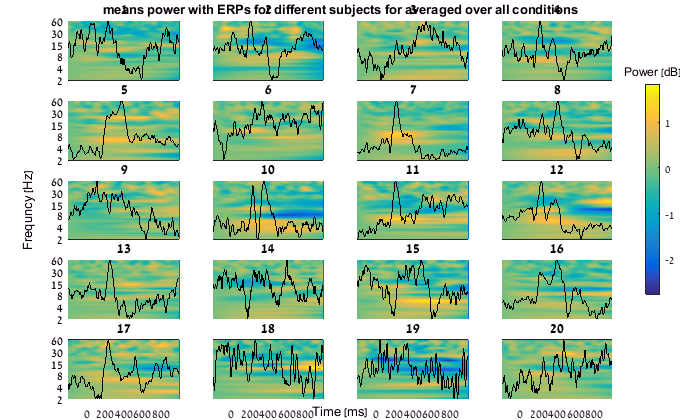

tic
figure;
title_str = 'means power with ERPs for different subjects for averaged over all conditions';
power_str = 'Power [dB]';
show_powers_tight(t,freqs, squeeze(mean(total_powers(:,u,:,:),3)), 4, title_str, power_str, squeeze(mean(total_erps(u,:,:),2)))

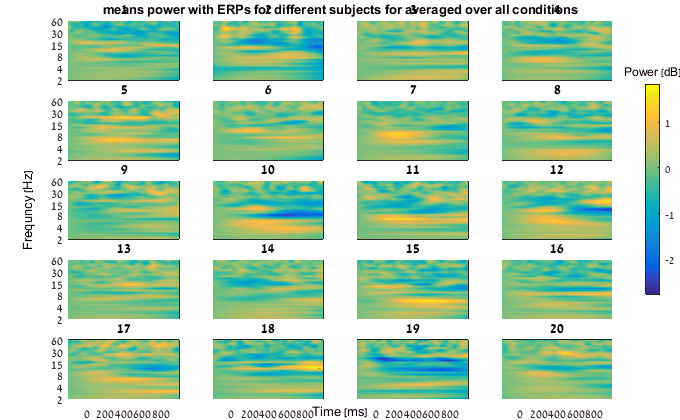


figure;
show_powers_tight(t,freqs, squeeze(mean(total_powers(:,u,:,:),3)), 4, title_str, power_str, [])

toc

Elapsed time is 3.416819 seconds.


display total ERP with all trials

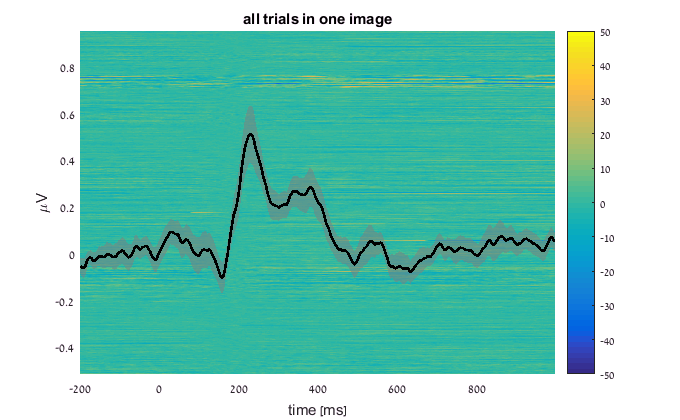


erps = squeeze(mean(total_erps(u,:,:), 2));
figure
hold on

imagesc(t, [min(erps(:)), max(erps(:))]*0.5, squeeze(norm_trials)')

caxis([min(norm_trials(:)) max(norm_trials(:))]);
caxis([-50 50]);


varplot(t, erps, 'linewidth',2,'color','k');

axis tight
axis xy
title 'all trials in one image'
xlabel 'time [ms]'
ylabel '\muV'

colorbar

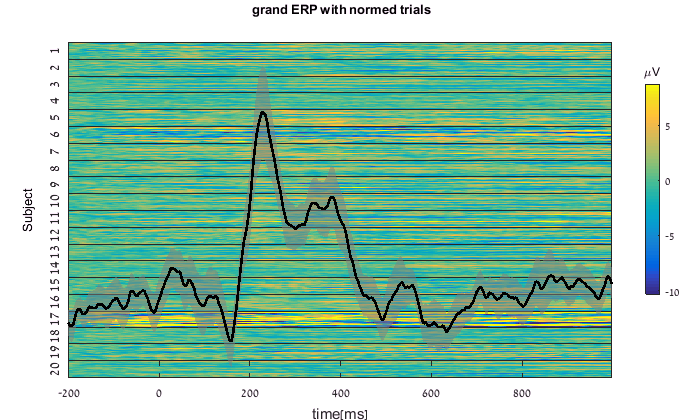


figure;
c = mat2cell(squeeze(norm_trials(u,1,:))', subject_num_trials, length(t));
show_trials_tight(t, c, 1, 'grand ERP with normed trials', '\muV')
axes('Position',[0.1 0.1 0.8 0.8],'Xlim',[0 1],'Ylim',[0 1],'Box','off','Visible','off','Units','normalized', 'clipping' , 'off');
varplot(t, erps, 'linewidth',2,'color','k');
set(gca, 'Color', 'none')
set(gca,'XTick',[]);
set(gca,'YTick',[]);

## Table of evoked-induced

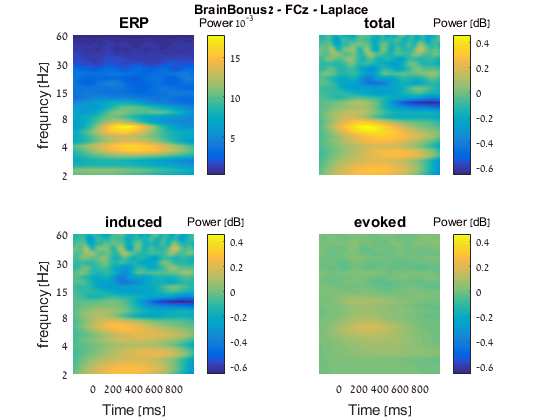

figure;
show4images(t,freqs, ...
    mean(mean(erps_powers(:,u,:,:),4),3), ...
    mean(mean(total_powers(:,u,:,:),4),3), ...
    mean(mean(sub_powers(:,u,:,:),4),3), ...
    mean(mean(total_powers(:,u,:,:)-sub_powers(:,u,:,:),4),3), ...
    'BrainBonus2 - FCz - Laplace', ...
    'surf')

## Table of evoked-induced (Other form)

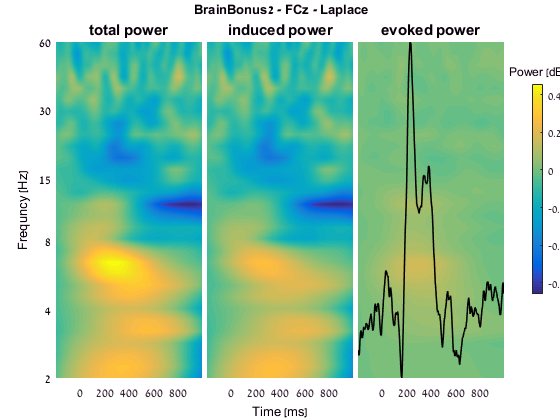

figure;
datas2show = cat(3, ...
                mean(mean(total_powers(:,u,:,:),4),3), ...
                mean(mean(sub_powers(:,u,:,:),4),3), ...
                mean(mean(total_powers(:,u,:,:)-sub_powers(:,u,:,:),4),3) ...
                );
overlap_data = zeros(size(datas2show,2), size(datas2show,3));
overlap_data(:, 1) = nan;
overlap_data(:, 2) = nan;
overlap_data(:, 3) = mean(total_erps(u,:),2);

% title_freq = sprintf('subject=%d, resampled (%d X %d)', subj_ind, m, n);
show_powers_tight(t, freqs, datas2show, ...
3, 'BrainBonus2 - FCz - Laplace', 'Power [dB]', overlap_data, ...
[], ...
[], {'total power', 'induced power', 'evoked power'}, 0.03 , 0.1, 0.1)

% colormap jet
%title_y, col_titles, gap,  marg_h, marg_w)

% ylabel [Au]
% xlabel 'time [ms]'
% title(['all data in one place (condition: ' condition])

%% Plotting ERPs
  
% plotting Fz, Pz and FCz
%     channels = {'Fz', 'Pz', 'FCz'};
%     t = window / srate;
%     
%     ERPfigure
%     hold all
%     for ch = channels
%         ch_segs = squeeze(SEGS(:,strcmp(channel_names, ch),:));
%         varplot(t,ch_segs);
%     end
%     
%     xlabel t[ms]
%     ylabel Power[Au]
%     title(['ERP of channels: ' strjoin(channels, ', ') 'in file' FileName])
%     legend(channels )
%     
%     hold off
%     

